# Music, Brain, and Emotions: An Engaging Self-Experiment—Live-Analysis

2024-12-05, seung-goo.kim@ae.mpg.de

## TODOs

- [_] Import data and sanity check

- [_] Preprocessing: high-pass sampling & downsampling 

- [_] Intersubject correlation with a sliding window

- [_] Statistical inference with sign flipping

## SETUP

addpath ~/MATLAB-Drive/mpscog-ca25-mbe/musafx-online-analysis/code/matlab/func
mmo_addpath()

## IMPORT

## PREPROCESSING

HINT: highpass(TimeTable, CutoffFreq_Hz)  % 1 mHz

HINT: synchronize(TT1, TT2, ..., TTN)

## ISC

HINT: 

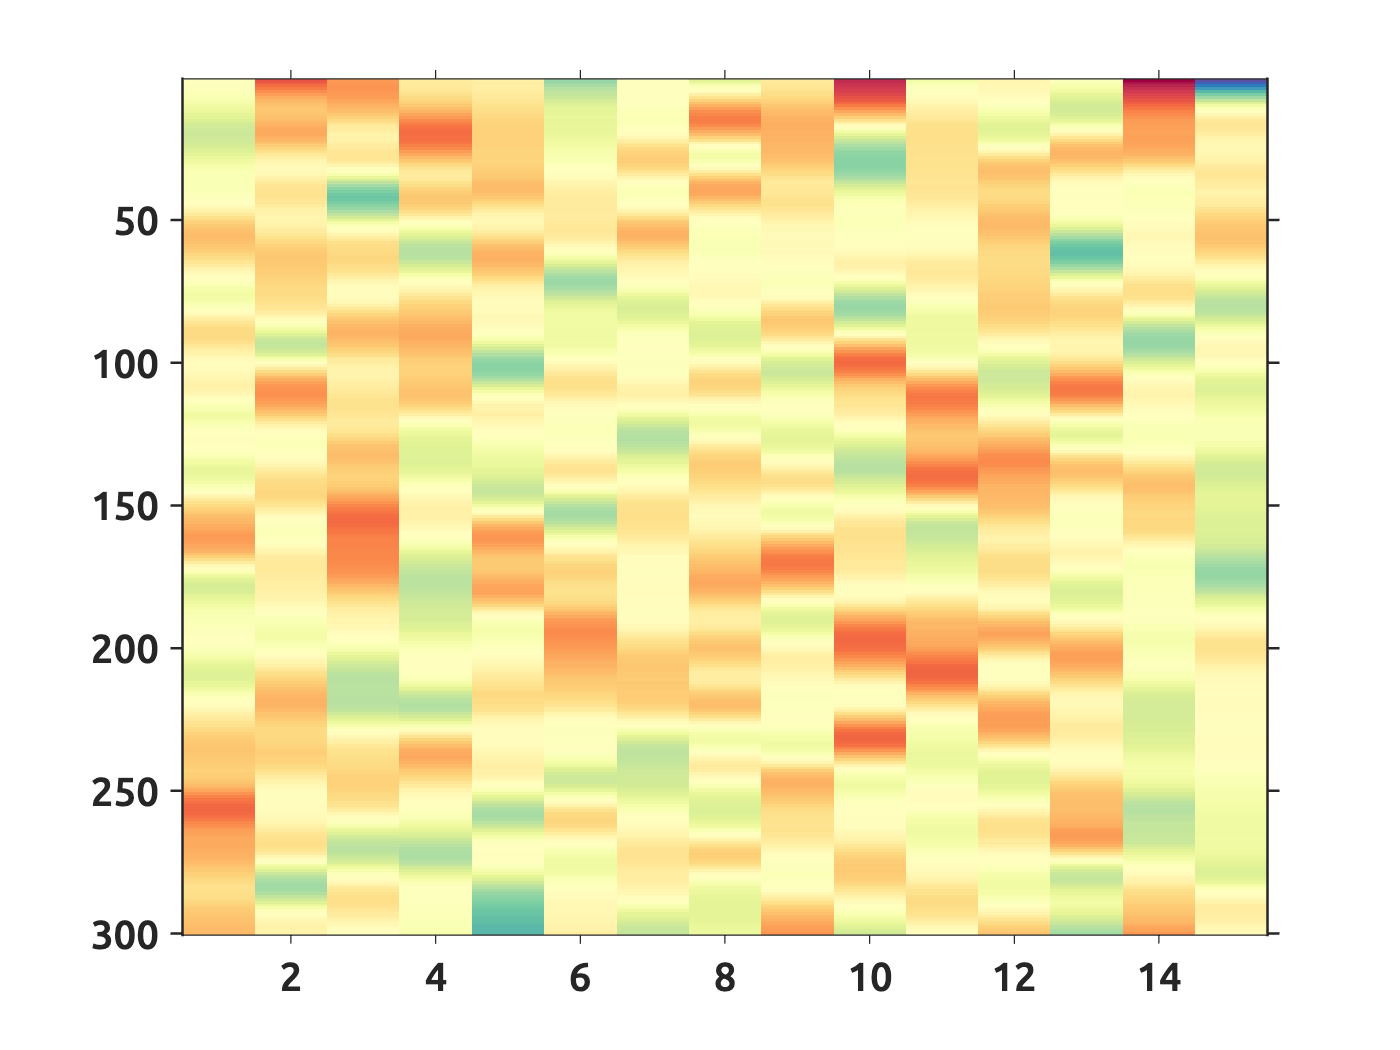

Y = smoothdata(normrnd(0, 1, [300,15]), 'gauss', 30);
imagesc(Y)
plot(mean(Y,2))
function isc = compute_isc(Y)
isc = [];
sumY = sum(Y,2);
for i = size(Y,2):-1:1
  isc(i) = corr(sumY-Y(:,i), Y(:,i));
end

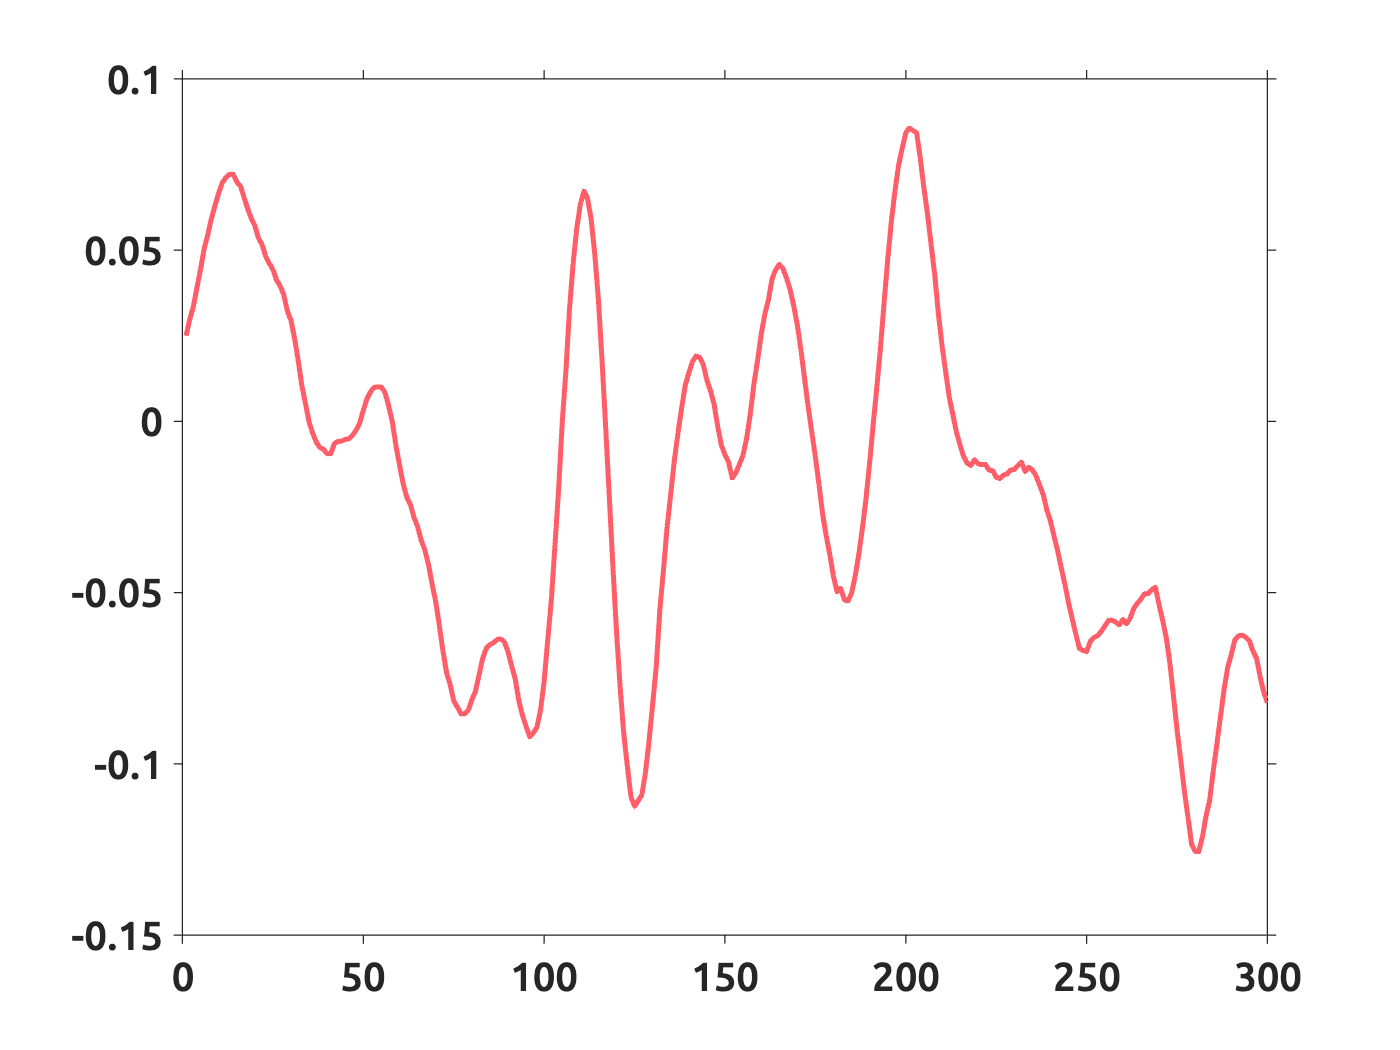

end


histogram(compute_isc(Y))
[~,p,~,st] = ttest(isc) % WOW!

## Statistical inference

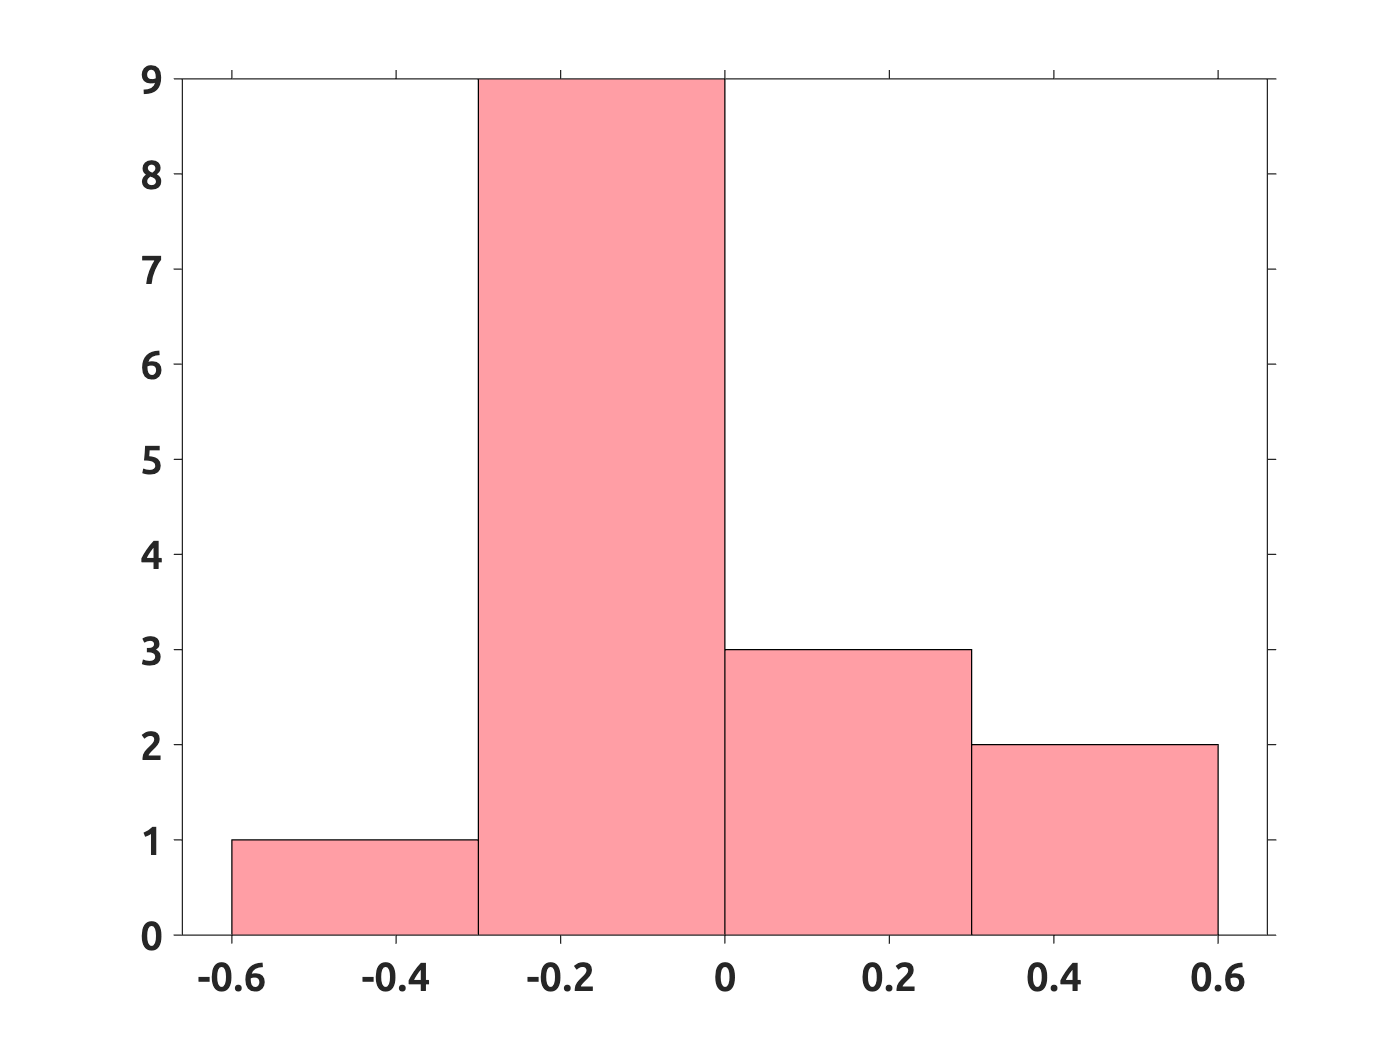

Y = smoothdata(normrnd(0, 1, [300,15]), 'gauss', 30) + rand(300,1)*0.3;
obsMeanIsc = mean(compute_isc(Y));
nullMeanIsc = [];
for k = 100:-1:1
  randSign = round(rand(1,size(Y,2)))*2-1;

  nullY = Y .* randSign;

p = 8.7431e-04

st = struct with fields:
    tstat: 4.2095
       df: 14
       sd: 0.1707


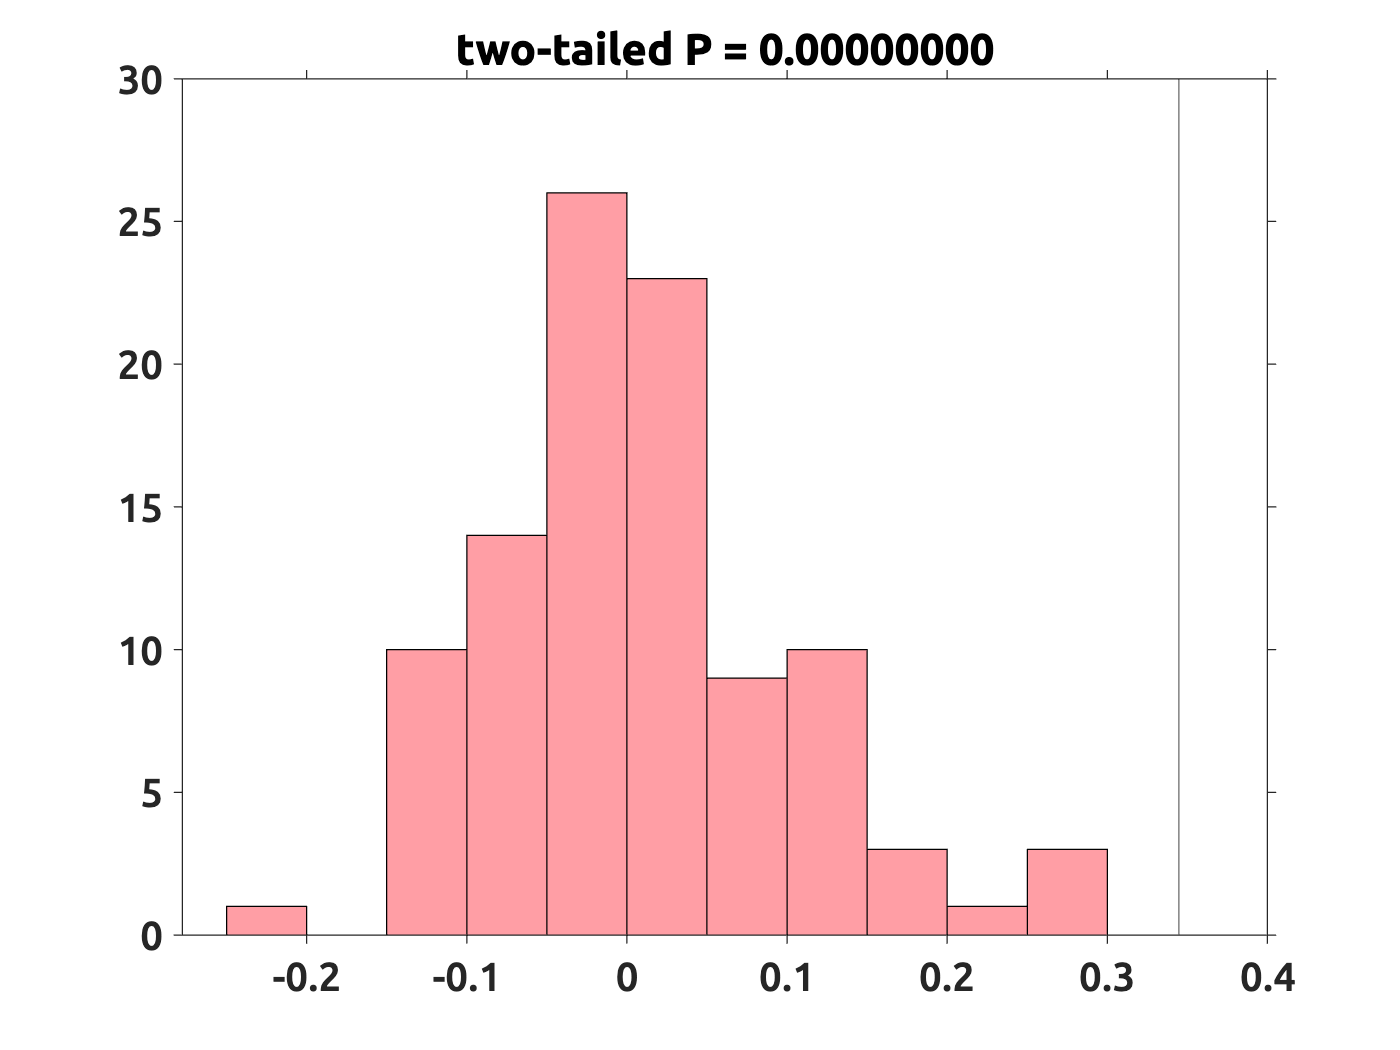

  nullMeanIsc(k) = mean(compute_isc(nullY));
end
histogram(nullMeanIsc)
xline(obsMeanIsc)

title(sprintf('two-tailed P = %.8f', min(mean(nullMeanIsc>obsMeanIsc), mean(nullMeanIsc<obsMeanIsc))*2))